% [~,threshold] = edge(img,'sobel');
% fudgeFactor = 0.5;
% BWs = edge(I,'sobel',threshold * fudgeFactor);
% 
% imagesc(BWs)
% title('Binary Gradient Mask')
% 
% se90 = strel('line',3,90);
% se0 = strel('line',3,0);
% 
% 
% BWsdil = imdilate(BWs,[se90 se0]);
% imagesc(BWsdil)
% title('Dilated Gradient Mask')
% 
% 
% BWdfill = imfill(img,'holes');
% imagesc(BWdfill)
% title('Binary Image with Filled Holes')
% 
% 
% BWnobord = imclearborder(BWdfill,4);
% imagesc(BWnobord)
% title('Cleared Border Image')
% 
% 
% seD = strel('diamond',1);
% BWfinal = imerode(BWnobord,seD);
% BWfinal = imerode(BWfinal,seD);
% imagesc(BWfinal)
% title('Segmented Image');
% 
% imagesc(labeloverlay(I,BWfinal))
% title('Mask Over Original Image')
% 
% 
% BWoutline = bwperim(BWfinal);
% Segout = I; 
% Segout(BWoutline) = 255; 
% imagesc(Segout)
% title('Outlined Original Image')

% inpict = im2double(rgb2gray(imread('image.jpeg')));
% outpict = medfilt2(inpict,[3 3], 'symmetric');
% outpict = imadjust(outpict,[0.15 0.85]);
% figure, imshow(outpict)

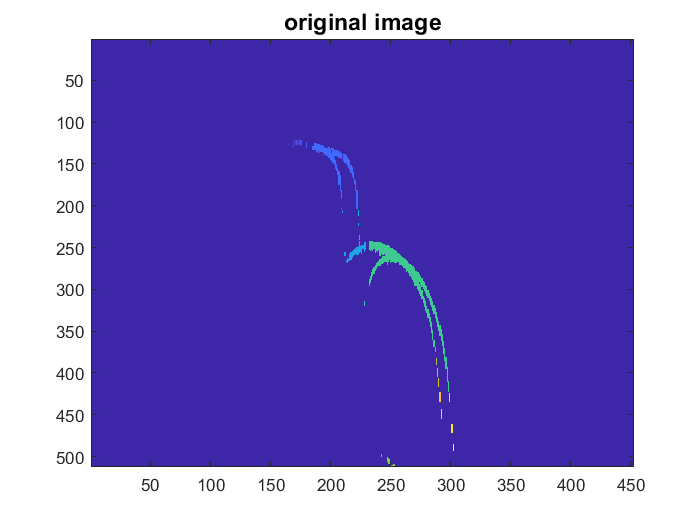

% %---------------------------------------------------------%
% %--Basic High pass and Low pass filter--------------------%
% %---------------------------------------------------------%
% I = imgDen_1;
% A = fft2(double(I)); % compute FFT of the grey image
% Y=fftshift(A); % frequency scaling
%  
% [M, N]=size(A); % image size
% D=30; % filter size parameter 
% % defining a typical low pass filter response H(f)
% % Low pass filter has value=1  in the 
% % low frequency region and value=0 in the high freq
% % region
% Lo(1:M,1:N)=0;
% Lo(0.5*M-D:0.5*M+D,0.5*N-D:0.5*N+D)=1;
% 
% % defining a typical high pass filter response H(f)
% % High pass filter has value=1 in
% % the high frequency region and value=0 in the low
% % frequency region
% Hi(1:M,1:N)=1;
% Hi(0.5*M-D:0.5*M+D,0.5*N-D:0.5*N+D)=0;
% 
% % Filtered image=filter response*fft(original image)
% J=Y.*Lo;
% J1=ifftshift(J);
% B1=ifft2(J1);
% 
% K=Y.*Hi;
% K1=ifftshift(K);
% B2=ifft2(K1);
% %----visualizing the results----------------------------------------------
% figure(1)
% imagesc(I);
% title('original image','fontsize',14)

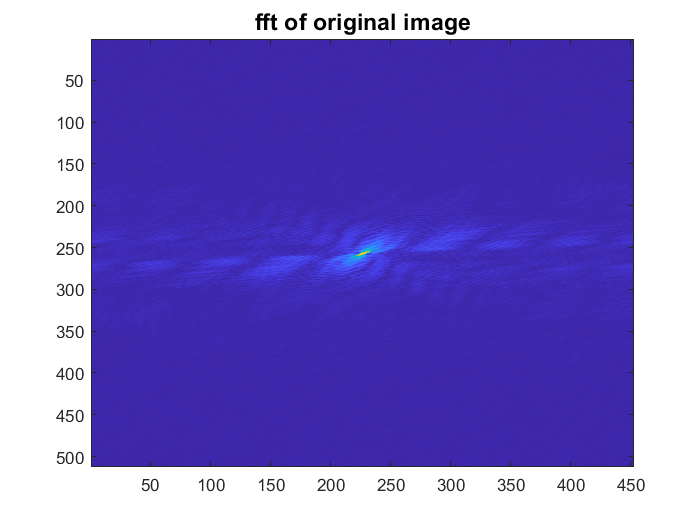

% figure(2)
% imagesc(abs(fftshift(A)))
% title('fft of original image','fontsize',14)

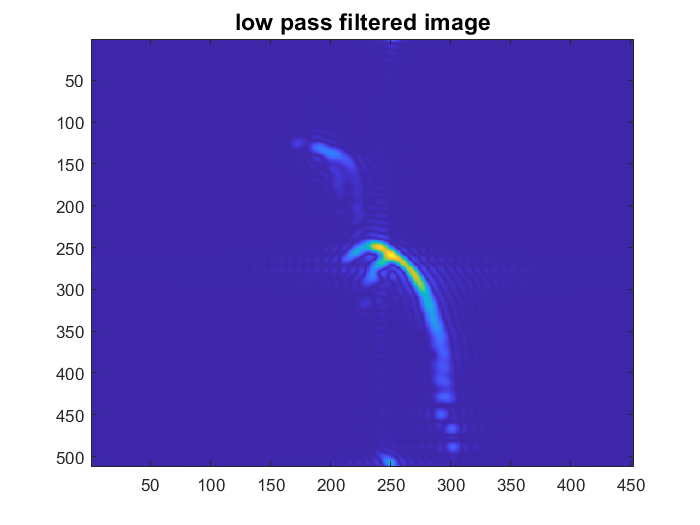

% figure(3)
% imagesc(abs(B1))
% title('low pass filtered image','fontsize',14)

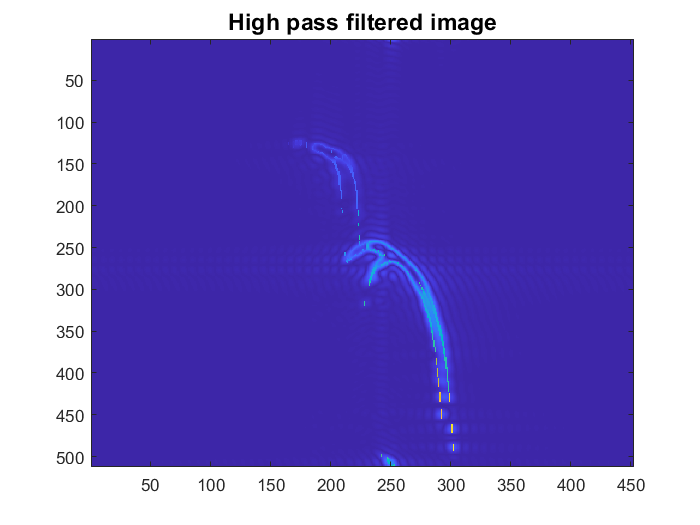

% figure(4)
% imagesc(abs(B2))
% title('High pass filtered image','fontsize',14)

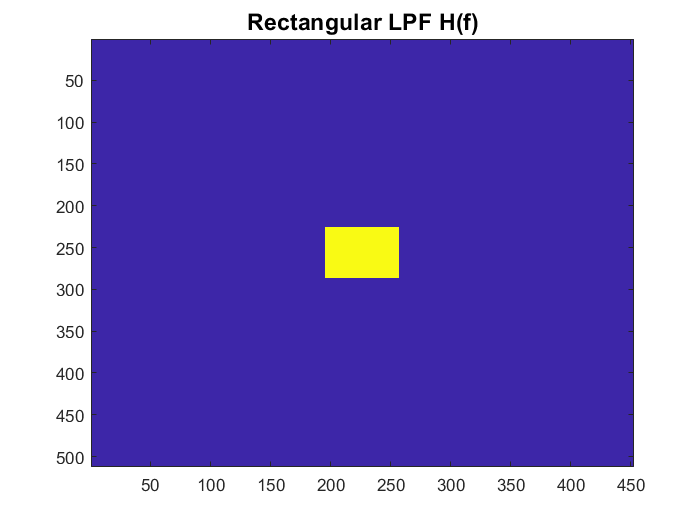

% figure(5)
% imagesc(Lo,[0 1])
% title('Rectangular LPF H(f)','fontsize',14)

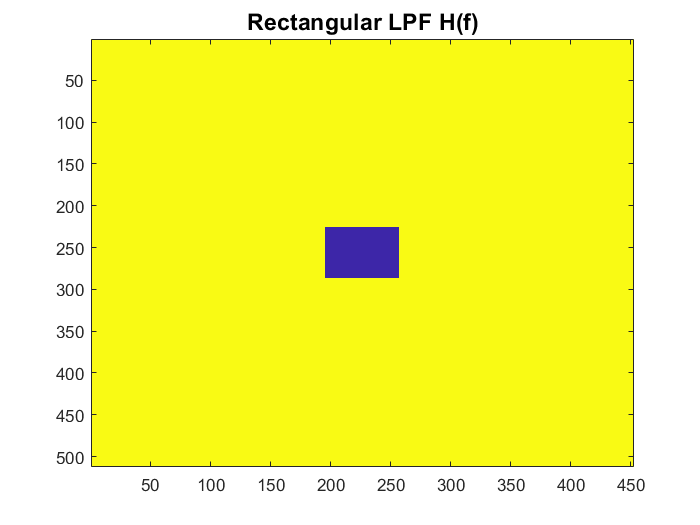

%    
% figure(6)
% imagesc(Hi,[0 1])
% title('Rectangular LPF H(f)','fontsize',14)

% %-------------------------------------------------------------------------

% findpeaks(Projx,'MinPeakProminence',4,'Annotate','extents')
% findpeaks(Projy,'MinPeakProminence',4,'Annotate','extents')
% 
% img = sharpened;
% z = medfilt1(Projx);
% ncolumnsXnrows = size(img);
%     for x = 1:ncolumnsXnrows(2)
%         for y = 1:ncolumnsXnrows(1)
%             if z(x) == 0
%                 img(y,x) = 0;
%             end
%         end
%     end 
% figure, imagesc(flip(img))
% %CustomPlot(IonogramData, img)
% 
% 
% img = sharpened;
% z = medfilt1(Projy);
% ncolumnsXnrows = size(img);
%     for x = 1:ncolumnsXnrows(2)
%         for y = 1:ncolumnsXnrows(1)
%             if z(x) == 0
%                 img(y,x) = 0;
%             end
%         end
%     end
% 
% figure, imagesc(flip(img))
%CustomPlot(IonogramData, img)


% zidifzero = find(z~=0);
% % zigualzero = find(z==0);
% %ansz = [1 3 4 5 7 8 9 11 12 13 15 17];
% 
% idx = find((diff(zidifzero)~=1)==1);
% % varzzz = zidifzero(diff(zidifzero)~=1);
% 
% % testdifzerodif(1) = zdifzero(idx)+1;
% % testdifzerodif(2) = zdifzero(idx+1)+1;
% 
% if isempty(idx) == false
%     
%     z1(1) = sum(z(zidifzero(1):zdifzero(idx(1))));
%     saveidxvar(1,:) = [zidifzero(1), zdifzero(idx(1))];
%     
%     if length(idx) == 1
%         z1(2) = sum( z(zdifzero(idx(1)+1):zidifzero(end)) );
%         saveidxvar(2,:) = [zdifzero(idx(1)+1), zidifzero(end)];
%     else
%         for i = 2:length(idx)
%             if i ~= length(idx)
%                 z1(i) = sum(z(zdifzero(idx(i)+1):zidifzero(idx(i+1))));
%                 saveidxvar(i,:) = [zdifzero(idx(i)+1), zidifzero(idx(i+1))];
%                 %saveidx = zdifzero(idx(i)+1):zidifzero(idx(i+1));
%             else
%                 z1(i) = sum( z(zdifzero(idx(i)+1):zidifzero(end)) );
%                 saveidxvar(i,:) = [zdifzero(idx(i)+1), zidifzero(end)];
%             end 
%         end
%     end
%     
% else
%     disp('Done')
% end
% 
% for i = 1:length(z1)
%     if z1(i) < mean(z1)
%         z(saveidxvar(i,1):saveidxvar(i,2)) = 0;
%     end
% end
% zvarxd = (z ~= 0);
% neinz = zvarxd.*Projy;
% 
% ncolumnsXnrows = size(img);
%     for x = 1:ncolumnsXnrows(2)
%         for y = 1:ncolumnsXnrows(1)
%             if neinz(x) <= 0
%                 img(y,x) = 0;
%             end
%         end
%     end
% 
% figure, imagesc(flip(img))

% ncolumnsXnrows = size(img);
%     for x = 1:ncolumnsXnrows(2)
%         for y = 1:ncolumnsXnrows(1)
%             if z(x) //  < mean(z1)
%                 img(y,x) = 0;
%             end
%         end
%     end




% z1(1) = sum(z(zidifzero(1):testdifzerodif(1)))
% z1(2) = sum(z(testdifzerodif(2):zidifzero(end)))

% mean(z1);
% 
% if isempty(nope) == true
%     disp('000')
% else
%     disp('fck')
% end


% testdifzeroigual1 = zdifzero(diff(zidifzero)==1);
% 
% 
% 
% 
% test2 = zdifzero(diff(zdifzero)==1);

% outpict = medfilt2(sharpened, [4, 3]);
% imshowpair(sharpened, outpict,'montage')
% %outpict = imadjust(outpict,[0.15 0.85]);
% figure; imagesc(fftshift(log10(abs(fft2(outpict)))+1)), colorbar;
% 
% figure, imagesc(outpict)

% imgVar_ = sharpened;
% imgVar_ = imgVar_(imgVar_~=0);
% 
% boxplot(imgVar_)

% % Eliminate all vertical and diagonal lines in MATLAB
% clear; close all;
% %Input Image
% A = imread('5.png');
% % figure, imshow(A);
% 
% C=medfilt2(A,[3 5]);
% % figure,imshow(C);
% 
% D=imfill(C);
% % figure,imshow(D);
% 
% %Image obtained using MATLAB function 'edge'    
% E=edge(D,'canny',[0.01 .02],4);
% figure, imshow(E); title('Image obtained using MATLAB function');
% 
% image=E;
% img=double(image);
% img = imgaussfilt(img,.5);
% % imshow(img)
% zz_out = zeros(size(img));
% % se = strel('line',3,-90);
% % zz = imerode(img,se);
% % se2 = strel('line',3,0);
% % zz2 = imerode(img,se2);
% for ii = -5:.1:5
%     se = strel('line',20,ii);
%     zz = imerode(img,se);
%     zz_out = or(zz,zz_out);
% end
% % zz_out = img-zz;
% figure, imshow(zz_out);

% % Hough transform

% % I crop only the intresting part for illustration:
% BW = edge(Two_dim(1:1000,:),'canny');
% subplot 131
% imagesc(Two_dim(1:1000,:))
% title('Original image')
% axis xy
% [H,theta,rho] = hough(BW); % preform Hough transform
% subplot 132
% P = houghpeaks(H,10,'NHoodSize',[1 1]); % find the peaks in the transformation
% lines_found = houghlines(BW,theta,rho,P,...
%     'FillGap',50,'MinLength',1); % convert the peaks to line objects
% imagesc(Two_dim(1:1000,:)), hold on
% result = Two_dim(1:1000,:);
% for k = 1:length(lines_found)
%    % extract one line:
%    xy = [lines_found(k).point1; lines_found(k).point2];
%    % Plot the detected lines:
%    plot(xy(:,1),xy(:,2),'LineWidth',1,'Color','green');
%    % remove the lines from the image:
%    % note that I take a buffer of 3 to the 'width' of the line
%    result(xy(1,2):xy(1,2)+3,xy(1,1):xy(2,1)) = 0;
% end
% title('Detected lines')
% axis xy
% subplot 133
% imagesc(result)
% title('Corrected image')
% axis xy


% %---------------------------------------------------------%
% %--Gaussian High pass and Low pass filter--------------------%
% %---------------------------------------------------------%
% clc
% close all
% clear all
% RGB=imread('Your Image');
% I=rgb2gray(RGB); % convert the image to grey 
% A = fft2(double(I)); % compute FFT of the grey image
% A1=fftshift(A); % frequency scaling
% % Gaussian Filter Response Calculation
% [M N]=size(A); % image size
% R=10; % filter size parameter 
% X=0:N-1;
% Y=0:M-1;
% [X Y]=meshgrid(X,Y);
% Cx=0.5*N;
% Cy=0.5*M;
% Lo=exp(-((X-Cx).^2+(Y-Cy).^2)./(2*R).^2);
% Hi=1-Lo; % High pass filter=1-low pass filter
% % Filtered image=ifft(filter response*fft(original image))
% J=A1.*Lo;
% J1=ifftshift(J);
% B1=ifft2(J1);
% K=A1.*Hi;
% K1=ifftshift(K);
% B2=ifft2(K1);
% %----visualizing the results----------------------------------------------
% figure(1)
% imshow(I);colormap gray
% title('original image','fontsize',14)
% figure(2)
% imshow(abs(A1),[-12 300000]), colormap gray
% title('fft of original image','fontsize',14)
% figure(3)
% imshow(abs(B1),[12 290]), colormap gray
% title('low pass filtered image','fontsize',14)
% figure(4)
% imshow(abs(B2),[12 290]), colormap gray
% title('High pass filtered image','fontsize',14)
% figure(5)
%    mesh(X,Y,Lo)
%    axis([ 0 N 0 M 0 1])
%    h=gca; 
%    get(h,'FontSize') 
%    set(h,'FontSize',14)
%    title('Gaussiab LPF H(f)','fontsize',14)
%    
% figure(6)
%    mesh(X,Y,Hi)
%    axis([ 0 N 0 M 0 1])
%    h=gca; 
%    get(h,'FontSize') 
%    set(h,'FontSize',14)
%    title('Gaussian HPF H(f)','fontsize',14)
% %-------------------------------------------------------------------------